clear;
m = 100000;
n = 10000;
density = 1e2/m;
max_iter = 1000;
lda = 100;
rho = 0.1;
abs_tolerance = 1e-4;
rel_tolerance = 1e-3;
x = sprand(m, n, density);
theta = rand(n, 1);
noise = -0.5 + rand(m, 1);
y = x*theta + noise;
iters = 1000;
alpha = 0.001;
theta_old = rand(n, 1);

theta = theta_old;

err_regression = [];
theta_regression = [];

err_regression = [err_regression; (1/(2*m))*sum((y-x*theta).^2)];
theta_regression = [theta_regression; theta'];

tic
for i = 1:iters
    theta = theta + alpha*(x'*(y - (x*theta)));
    err_regression = [err_regression; (1/(2*m))*sum((y-x*theta).^2)];
    theta_regression = [theta_regression; theta'];
end
toc

Elapsed time is 64.906910 seconds.


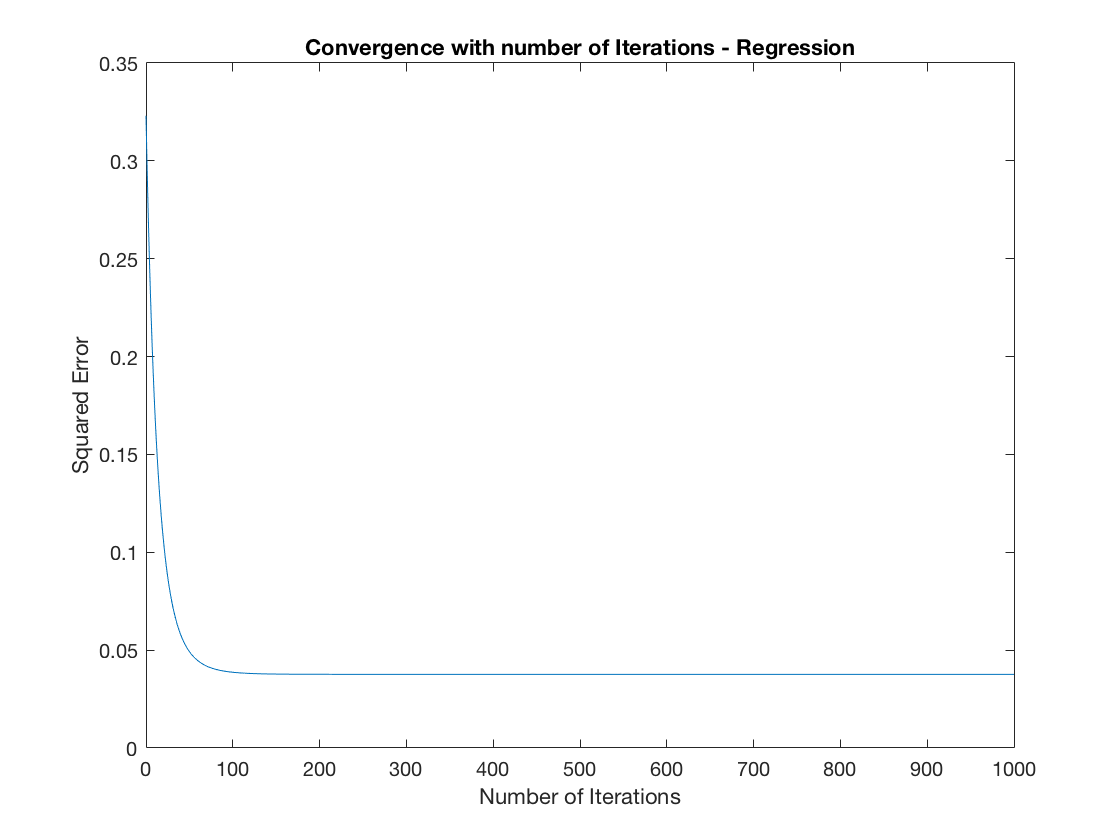

iterations = (0:iters)';
figure;
plot(iterations, err_regression);
hold on;
xlabel('Number of Iterations');
ylabel('Squared Error');
title('Convergence with number of Iterations - Regression');

theta = theta_old;


ldas = 0.1:0.1:1.2;
lda_errs = [];

tic
for lda=ldas
    for i = 1:iters
        theta = theta + alpha*(x'*(y - (x*theta))) - alpha*lda*theta;
    end
    lda_errs = [lda_errs; (1/(2*m))*sum((y-x*theta).^2)];
end
toc

Elapsed time is 123.755536 seconds.


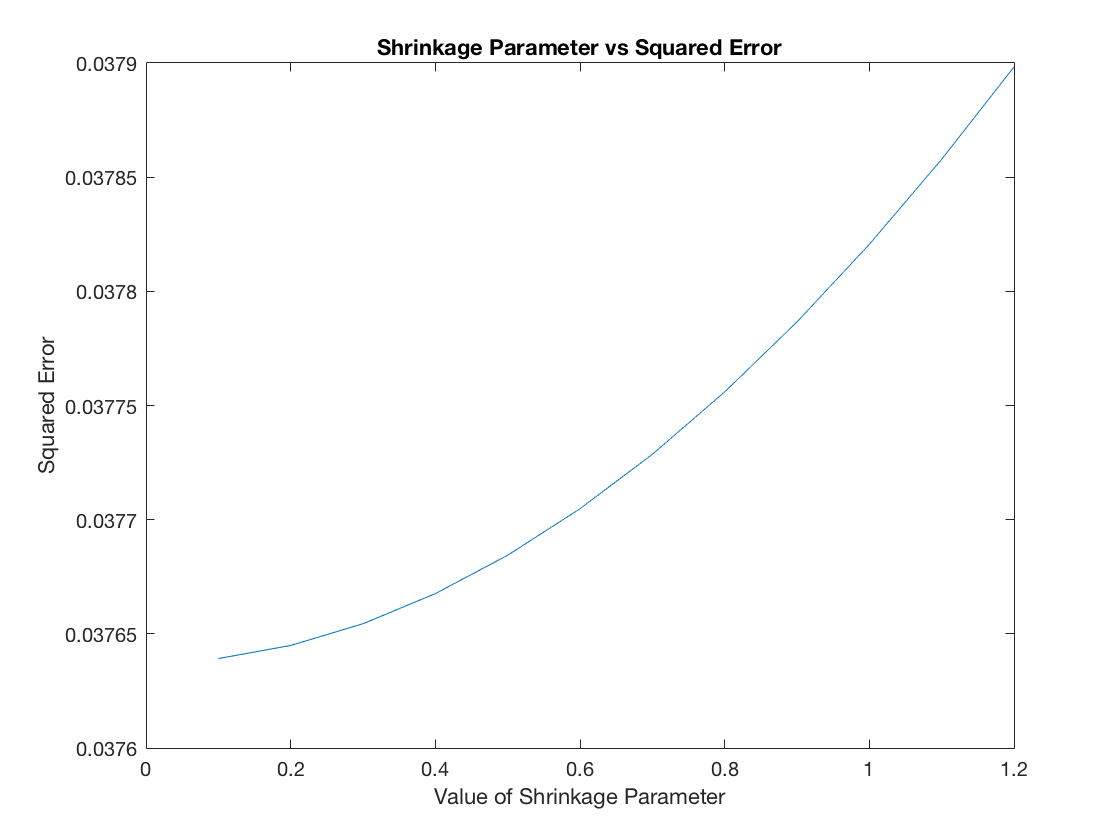


figure;
plot(ldas, lda_errs);
xlabel('Value of Shrinkage Parameter')
ylabel('Squared Error')
title('Shrinkage Parameter vs Squared Error')


[j, i] = min(lda_errs);
lda = ldas(i);

theta = theta_old;


theta_ridge = [];
err_ridge = [];

theta_ridge = [theta_ridge; theta'];
err_ridge = [err_ridge; (1/(2*m))*sum((y-x*theta).^2)];

tic
for i = 1:iters
    theta = theta + alpha*(x'*(y - (x*theta))) - alpha*lda*theta;
    theta_ridge = [theta_ridge; theta'];
    err_ridge = [err_ridge; (1/(2*m))*sum((y-x*theta).^2)];
end
toc

Elapsed time is 71.794483 seconds.


theta_bar_plot = [theta_ridge(size(theta_ridge, 1), 50:64)' theta_regression(size(theta_regression, 1), 50:64)']

theta_bar_plot =     0.7896    0.7910
    0.7139    0.7150
    0.8180    0.8204
    0.5161    0.5161
    0.2409    0.2405
    0.5966    0.5972
    0.7969    0.7981
    0.8521    0.8540
    0.2433    0.2421
    0.3015    0.3010


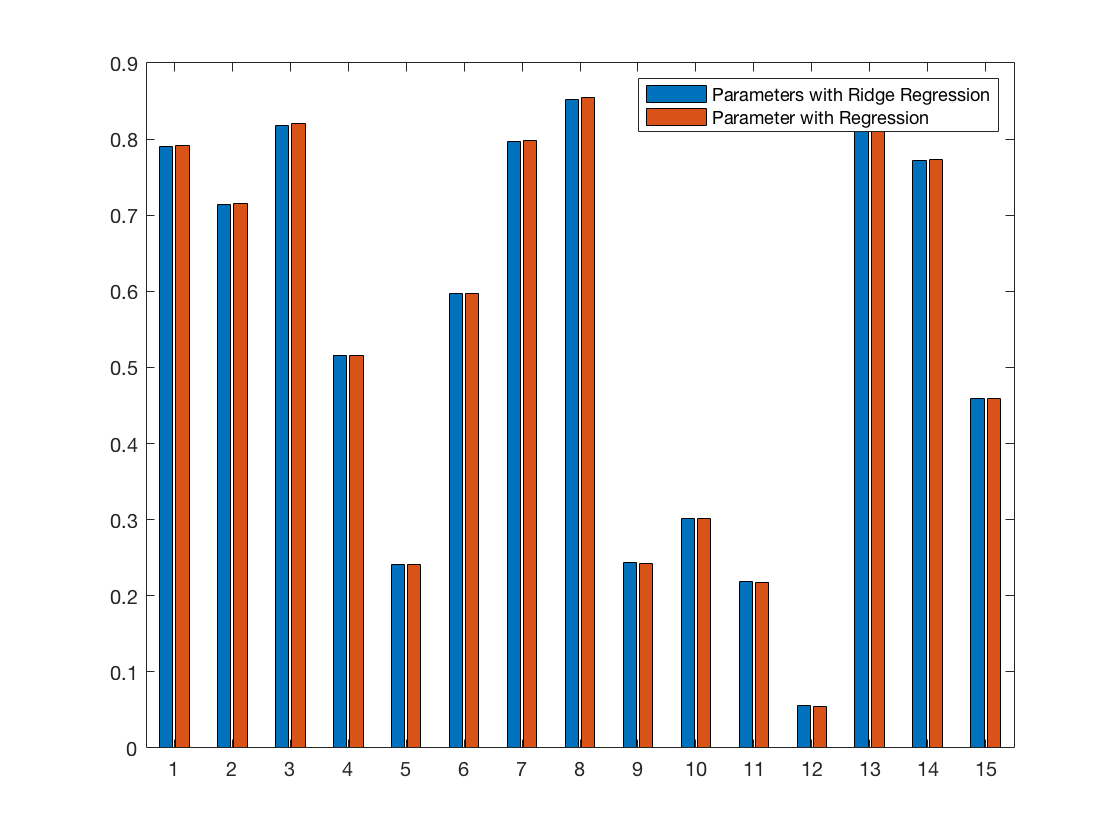

figure;
bar((1:15)', theta_bar_plot);
legend('Parameters with Ridge Regression', 'Parameter with Regression');

sum(theta_regression(size(theta_regression, 1), :) > theta_ridge(size(theta_ridge, 1), :))

ans = 5570

sum(theta_regression(size(theta_regression, 1), :) < theta_ridge(size(theta_ridge, 1), :))

ans = 4430

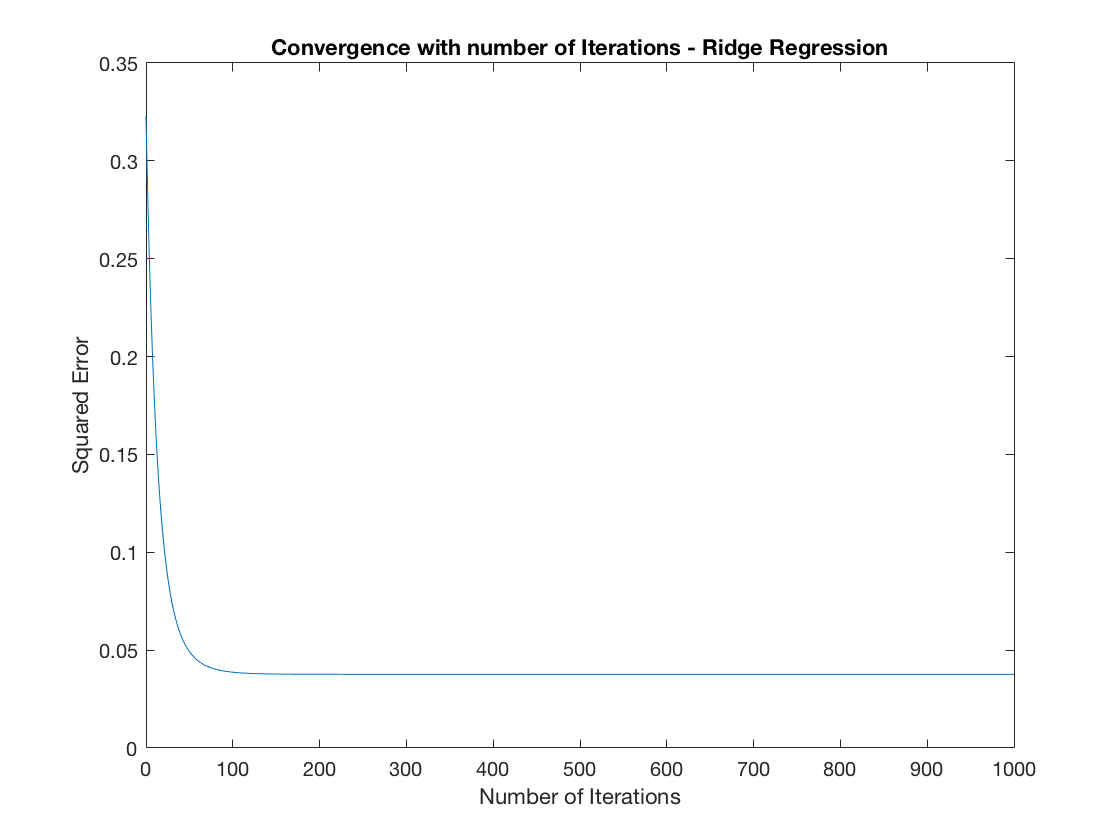

iterations = (0:iters)';
figure;
plot(iterations, err_ridge);
hold on;
xlabel('Number of Iterations');
ylabel('Squared Error');
title('Convergence with number of Iterations - Ridge Regression');

% y_old = y(:);
A = x;
b = y_old;

tic
L = chol(A'*A + rho*speye(n), 'lower');
U = L';
ATb = A'*b;

primal_residuals = [];
dual_residuals = [];
err_lasso = [];
%spy(L)
x_ad = zeros(n, 1);
y = zeros(n, 1);
z = zeros(n, 1);

err_lasso = [err_lasso; (1/(2*m))*sum((A*x_ad - b).^2)];

for i = 1:iters
%    i
    q = ATb + rho*(z - y);
    x_ad = U \ (L \ q);
    z_prev = z;
    xy = x_ad + y;
    z = max(0, xy - lda/rho) - max(0, -xy - lda/rho);
    y = xy - z;
    primal_residual = norm(x_ad - z);
    primal_residuals = [primal_residuals; primal_residual];
    dual_residual = norm(-rho*(z - z_prev));
    dual_residuals = [dual_residuals; dual_residual];
    epi_primal = sqrt(n)*abs_tolerance + rel_tolerance*max(norm(x_ad), norm(-z));
    epi_dual = sqrt(n)*abs_tolerance + rel_tolerance*norm(y);
    err_lasso = [err_lasso; (1/(2*m))*sum((A*x_ad - b).^2)];
    if primal_residual < epi_primal && dual_residual < epi_dual
        break;
    end
end
toc

Elapsed time is 32.747001 seconds.


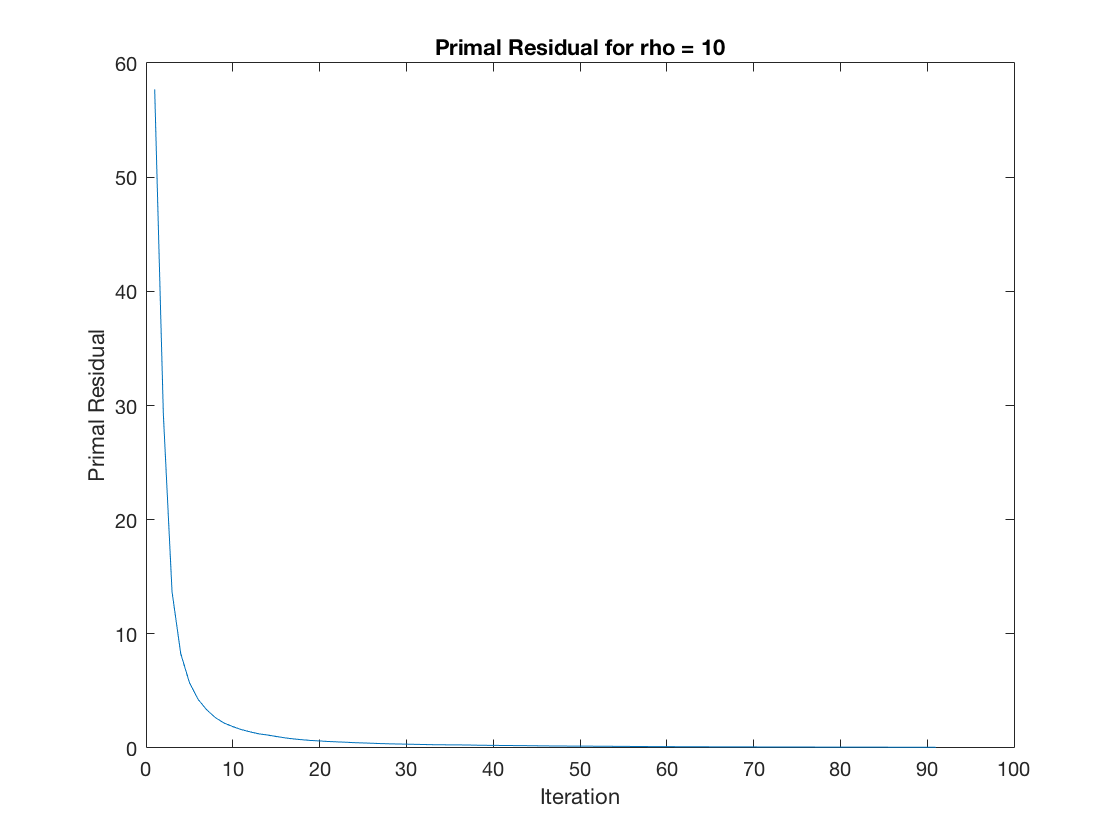


figure;
plot(primal_residuals);
hold on;
title('Primal Residual for rho = 10');
ylabel('Primal Residual');
xlabel('Iteration');

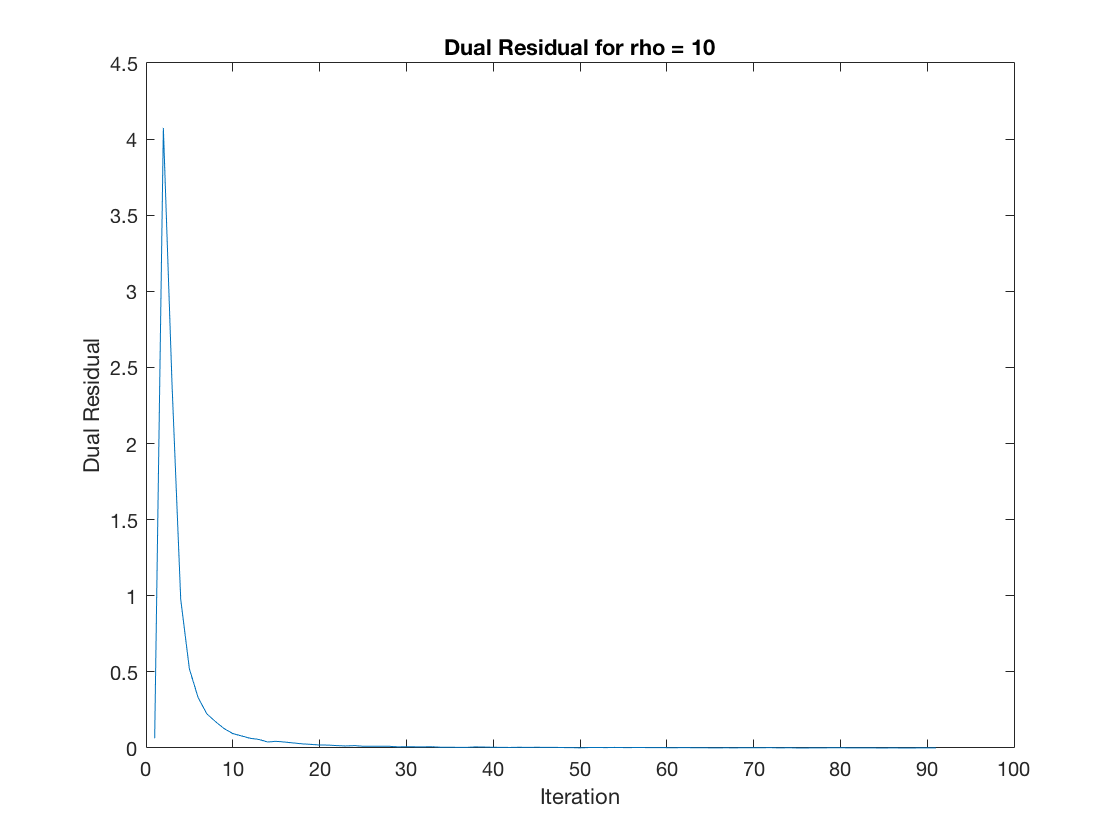


figure;
plot(dual_residuals);
hold on;
title('Dual Residual for rho = 10');
ylabel('Dual Residual');
xlabel('Iteration');


nnz(x_ad)/numel(x_ad)

ans = 1

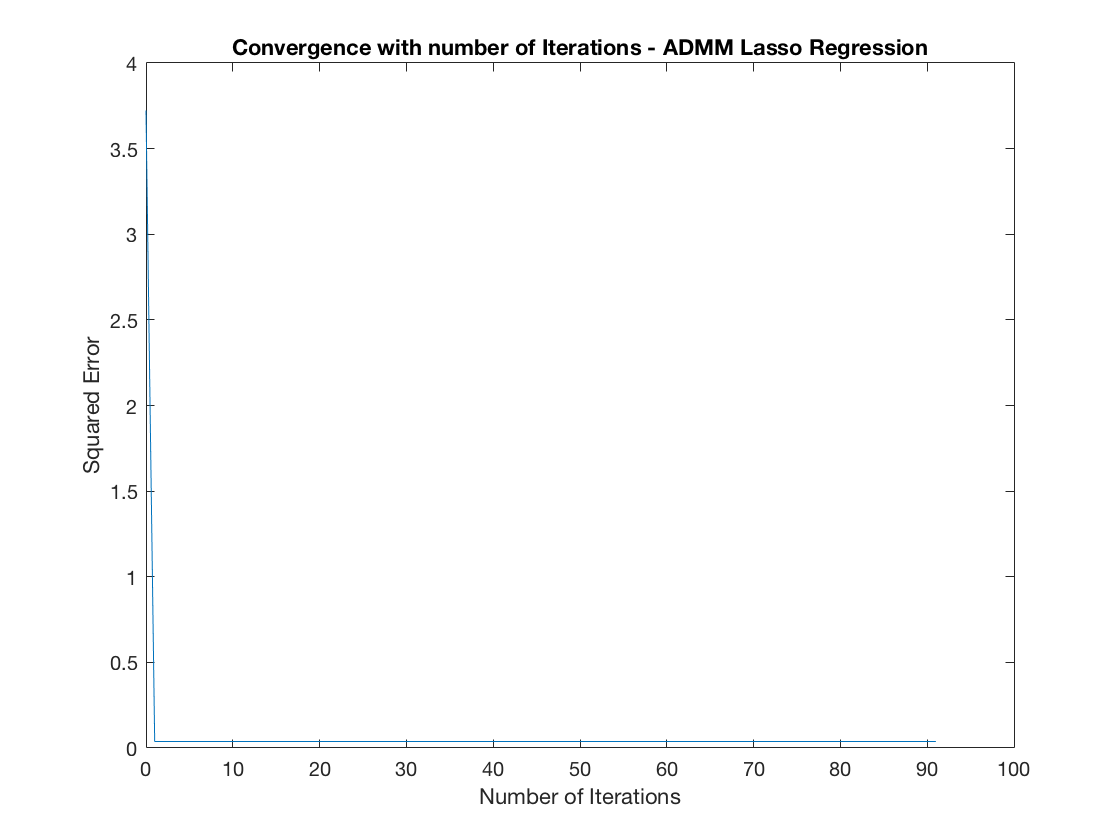

ans = 1001×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


ans = 0.0376

ans = 0.0376


iterations = (0:i)';
figure;
plot(iterations, err_lasso);
hold on;
xlabel('Number of Iterations');
ylabel('Squared Error');
title('Convergence with number of Iterations - ADMM Lasso Regression');